# Laboratorio di Automatica (prova del 12 Giugno 2018)

Riccardo Antonello ([riccardo.antonello@unipd.it](mail:riccardo.antonello@unipd.it)) and Angelo Cenedese ([angelo.cenedese@unipd.it](mail:angelo.cenedese@unipd.it)) 

June 12, 2018

Dept. of Information Engineering, University of Padova

## Esercizio 1

Si consideri il sistema di controllo in catena chiusa riportato in Fig. 1, con:


$$C(s)\,=\;k \left(\frac{1+\tau\,s}{1+\alpha\,\tau\,s}\right)\,,\qquad\qquad P(s) = \frac{1}{s^2}$$
  

Si assumano i seguenti valori per i parametri del controllore $C(s)$:


$$\alpha = 0.031\,,\qquad
\tau = 0.172\,,\qquad
k = 1$$


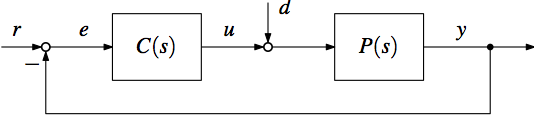

**Figura 1**: Sistema di controllo a retroazione unitaria dall'uscita.

Utilizzando *soltanto* le routines del Control System Toolbox (CST), si svolgano i seguenti punti:

1)  Valutare la risposta$y$ del sistema in catena chiusa ad un segnale di riferimento $r$ a gradino unitario, applicato all'istante $t=0$. Determinare successivamente sovraelongazione percentuale e tempo di assestamento al $5\%$ della risposta al gradino.

*Soluzione*.

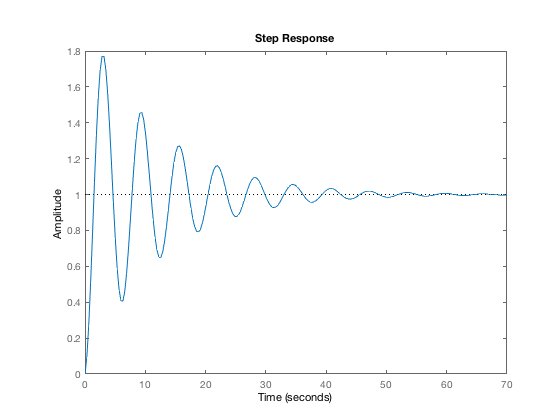

%    plant tf
sysP = tf(1, [1, 0, 0]);

%   controller tf
alpha = 0.031;
tau = 0.172;
sysC = tf([tau, 1], [alpha*tau, 1]);

%   loop tf
sysL = sysP*sysC;

%   closed-loop tf
sysT = feedback(sysL, 1);

%   step response
figure;
step(sysT);


%   step response info
stepinfo(sysT, 'SettlingTimeThreshold', 0.05);

2)  La risposta al gradino ottenuta al punto precedente presenta oscillazioni poco smorzate, segno che il margine di fase del sistema è basso. Calcolare pulsazione di attraversamento $\omega_{gc}$ e margine di fase $\varphi_m$ del sistema.

*Soluzione*.

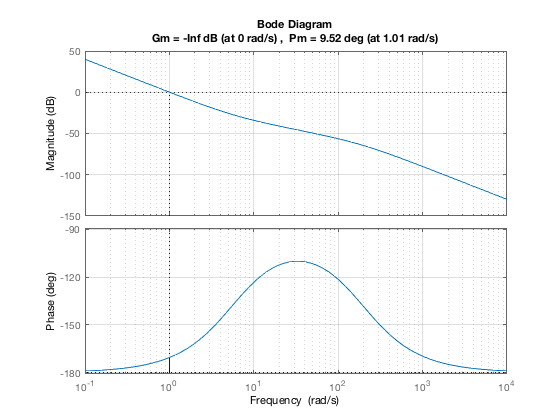

%   loop tf - stability margins
figure;
margin(sysL);
grid on;

3)  Al fine di ridurre le oscillazioni nella risposta al gradino, si intende modificare il guadagno $k$ del controllore in modo da portare il margine di fase del sistema ad un valore pari a $\varphi_m' = 60\,\mathrm{deg}$. 

Per fare ciò, si inizi con il determinare indicativamente, sul diagramma di Bode della funzione di trasferimento d'anello $L(s) = C(s) P(s)$, a quale valore di frequenza si raggiunge il margine di fase desiderato: tale valore di frequenza corrisponde alla nuova frequenza di attraversamento desiderata $\omega_{gc}'$.

*Nota*: in caso di soluzioni multiple, si consideri la soluzione a frequenza minima.

*Soluzione*.

Per ottenere un margine di fase pari a $\varphi_m' = 60\,\mathrm{deg}$, è necessario ricercare per quali valori di frequenza la funzione di trasferimento d'anello $L(s)$ ha fase pari a $\angle L(s) = -180 + 60 = -120 \,\mathrm{deg}$.

%   loop tf - Bode plot (phase)
w = logspace(-1, 4, 100);
[magL, phaL] = bode(sysL, w);

magL = squeeze(magL);
phaL = squeeze(phaL);

figure;
semilogx(w, phaL);
grid on;
xlabel('Frequency [rad/s]');
ylabel('Phase [deg]');

Dal grafico della fase, si nota che esistono due possibili valori di frequenza per i quali la fase è pari a $-120 \,\mathrm{deg}$. La soluzione a frequenza minima è $\omega_{gc}' \approx 11.7\,\mathrm{rad/s}$.


%   determination of new gain crossover freq
wgc = 11.7;
[~, pha] = bode(sysL, wgc)

pha = -119.9934

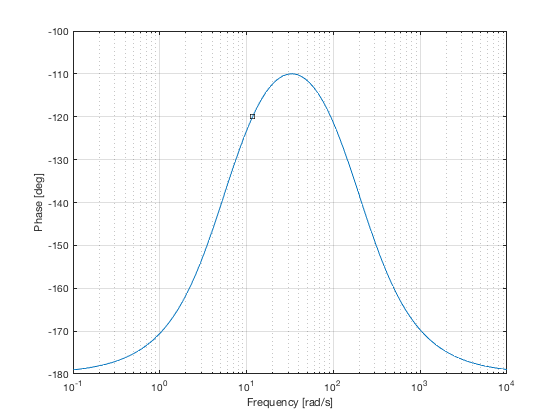


hold on;
semilogx(wgc, pha, 'sk');

4)  In corrispondenza della nuova frequenza di attraversamento desiderata $\omega_{gc}'$, si determini il modulo $|L(j\omega_{gc}')|$ della funzione di trasferimento d'anello. 

Allora, per fare in modo che $\omega_{gc}'$ diventi la nuova frequenza di attraversamento del sistema (a cui corrisponderà il margine di fase desiderato $\varphi_m'$), è necessario scegliere il guadagno del controllore pari a $k' = 1 / |L(j\omega_{gc}')|$.

*Soluzione*.

%   loop tf - Bode plot (magnitude)
figure;
semilogx(w, 20*log10(magL));
grid on;
xlabel('Frequency [rad/s]');
ylabel('Magnitude [dB]');

%   determination of required controller amplification
wgc = 11.7;
[mag, ~] = bode(sysL, wgc)

mag = 0.0164

magdB = 20*log10(mag)

magdB = -35.7116

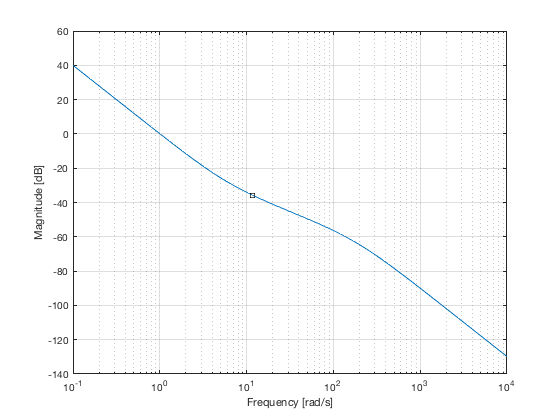


hold on;
semilogx(wgc, magdB, 'sk');


reqGainAdj = 1/mag

reqGainAdj = 61.0352

5)  Ripetere quanto riportato al punto 1, utilizzando il nuovo guadagno $k'$ del controllore, ottenuto al punto 4. 

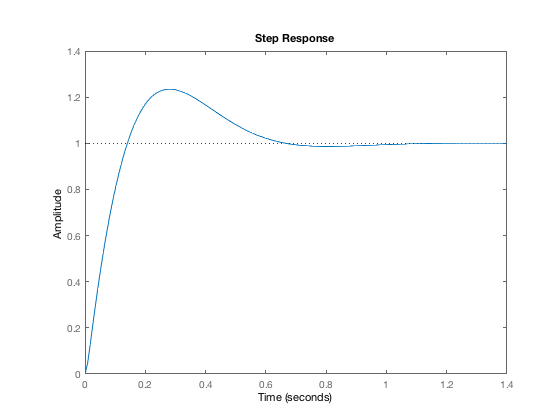

%   controller tf
sysC = reqGainAdj * sysC;

%   loop tf
sysL = sysP*sysC;

%   closed-loop tf
sysT = feedback(sysL, 1);

%   step response
figure;
step(sysT);


%   step response info
stepinfo(sysT, 'SettlingTimeThreshold', 0.05)

ans = struct with fields:
        RiseTime: 0.1040
    SettlingTime: 0.5454
     SettlingMin: 0.9073
     SettlingMax: 1.2346
       Overshoot: 23.4581
      Undershoot: 0
            Peak: 1.2346
        PeakTime: 0.2822
